# plot_pareto.mlx

Plotting result from Borg's MOEA solution of ProdAlloc Model (PAM)

## Load and merge data

% Available servers in the cluster, KUHNTUCKER?
sid = 2:7;
servers = arrayfun(@(y) sprintf('KUHNTUCKER%d',y),sid','UniformOutput',false);

% Merge output structures from all servers
Spam = cell(length(servers),1);
for i=1:length(servers)
	Spam{i,1} = load(['.\Output\' servers{i}],'Spam');
    Spam{i,1} = Spam{i,1}.Spam;
end
Spam = cell2mat(Spam);

% define grouping by realization and by seed
grp_real = cellfun(@(y) y(1),{Spam.grpid})';
grp_seed = cellfun(@(y) y(2),{Spam.grpid})';
n_Reals = length(unique(grp_real));
n_Seeds = length(unique(grp_seed));

% Create table of output
setsizes = arrayfun(@(y) size(Spam(y).objs,1),1:length(Spam))';
Tpam = [array2table(cell2mat({Spam.objs}'),'VariableNames',...
    {'Budget_diff','GW_prod_over','GW_prod_under','Prodcost_avg'}),...
    array2table(cell2mat(arrayfun(@(y) repmat([Spam(y).grpid,y],setsizes(y),1),...
    1:length(Spam),'UniformOutput',false)'),'VariableNames',...
    {'RID','Seed','SetID'})];   % SetID is the index of Spam
% replace SetID with seed_id*1000+real_id
Tpam.SetID = Tpam.Seed*1000+Tpam.RID;

% extract objs from the last row from all sets
objs = cell2mat(arrayfun(@(y) Spam(y).objs(end,:)',1:length(Spam),'UniformOutput',false))';
objs(:,4) = objs(:,4)*1e-3; % scale Cost objective

## Select realizations and seeds to plot 2-D Pareto Fronts

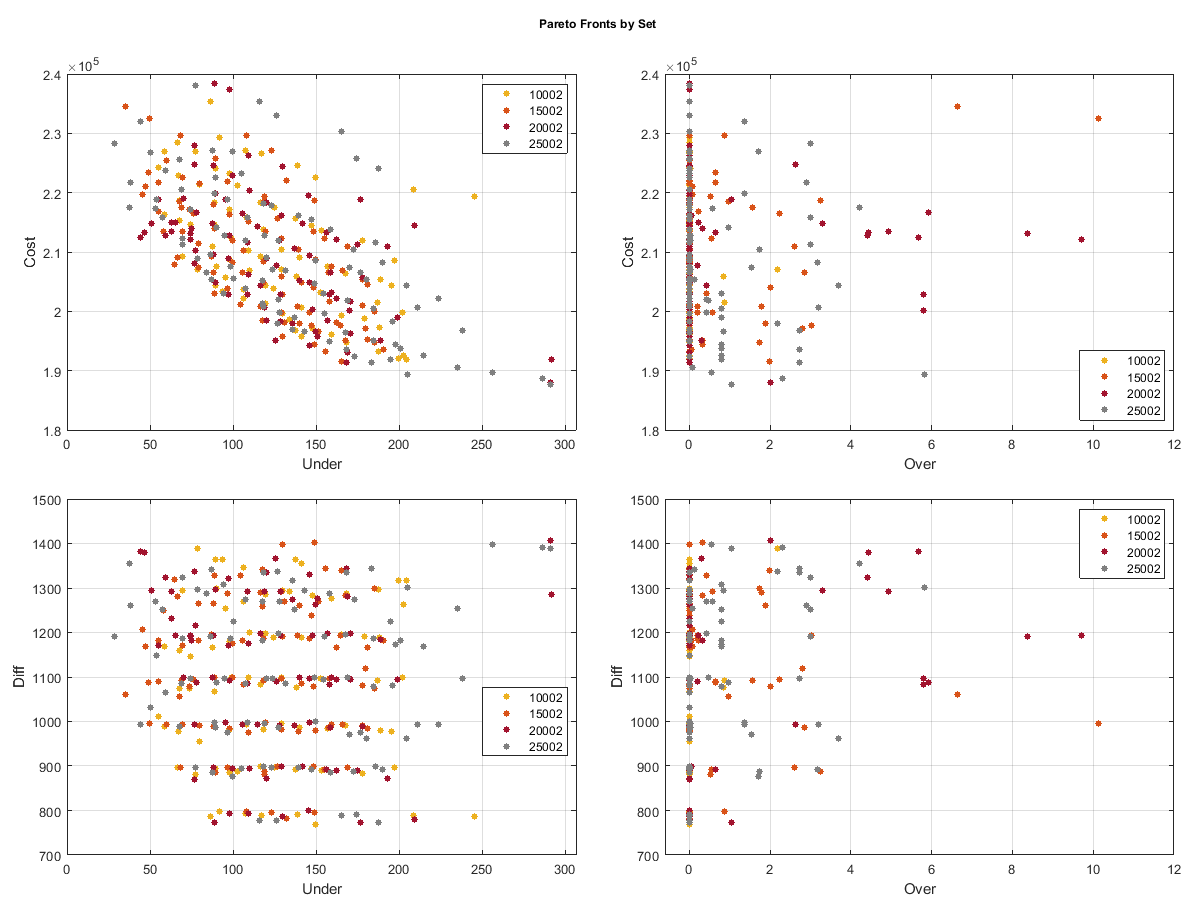

% extract objs by set
sel_reals = 2:2;
sel_seeds = [10,15,20,25];

Tsel = Tpam(ismember(Tpam.RID,sel_reals) & ismember(Tpam.Seed,sel_seeds),:);

% define color order
colorder0 = [...
         0         0         0;
         0    0.4470    0.7410;
    0.8500    0.3250    0.0980;
    0.9290    0.6940    0.1250;
    0.4940    0.1840    0.5560;
    0.4660    0.6740    0.1880;
    0.3010    0.7450    0.9330;
    0.5000    0.5000    0.5000;
    0.6350    0.0780    0.1840;
];
colorder = repmat(sortrows(colorder0,'descend'),...
    ceil(double(length(sel_reals)+length(sel_seeds))/size(colorder0,1)),1);

[~,a] = create2x2Axes('Pareto Fronts by Set');
subplot(a(1));
h = gscatter(Tsel.GW_prod_under,Tsel.Prodcost_avg,Tsel.SetID,...
    colorder,'o',4,'on','Under','Cost');
for n=1:length(h), set(h(n),'MarkerFaceColor',colorder(n,:)); end
grid on
subplot(a(2));
h = gscatter(Tsel.GW_prod_over,Tsel.Prodcost_avg,Tsel.SetID,...
    colorder,'o',4,'on','Over','Cost');
for n=1:length(h), set(h(n),'MarkerFaceColor',colorder(n,:)); end
grid on
subplot(a(3));
h = gscatter(Tsel.GW_prod_under,Tsel.Budget_diff,Tsel.SetID,...
    colorder,'o',4,'on','Under','Diff');
for n=1:length(h), set(h(n),'MarkerFaceColor',colorder(n,:)); end
grid on
subplot(a(4));
h = gscatter(Tsel.GW_prod_over,Tsel.Budget_diff,Tsel.SetID,...
    colorder,'o',4,'on','Over','Diff');
for n=1:length(h), set(h(n),'MarkerFaceColor',colorder(n,:)); end
grid on

## Select realizations and seeds to plot 3-D Pareto Fronts

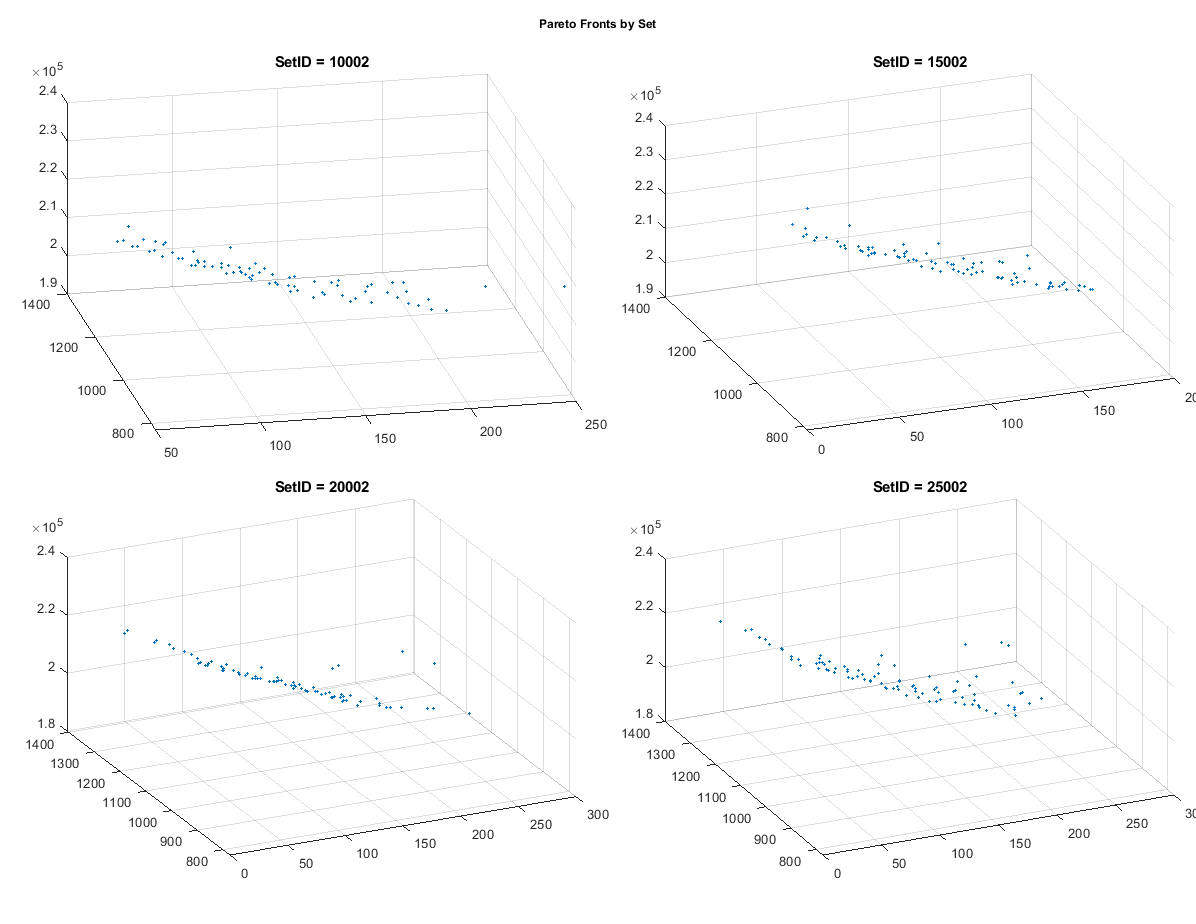

% loop through all selection sets
setids = unique(Tsel.SetID);

for k=1:length(setids)
    if mod(k-1,4)==0, [~,a] = create2x2Axes('Pareto Fronts by Set'); end
    subplot(a(mod(k-1,4)+1))
    scatter3(Tsel.GW_prod_under(Tsel.SetID==setids(k)),...
        Tsel.Budget_diff(Tsel.SetID==setids(k)),...
        Tsel.Prodcost_avg(Tsel.SetID==setids(k)),4,'filled');
    xlabel('Under');
    ylabel('Diff');
    zlabel('Cost')
    title(sprintf('SetID = %d',setids(k)));
end

## Multiobjective Line Plots by Set

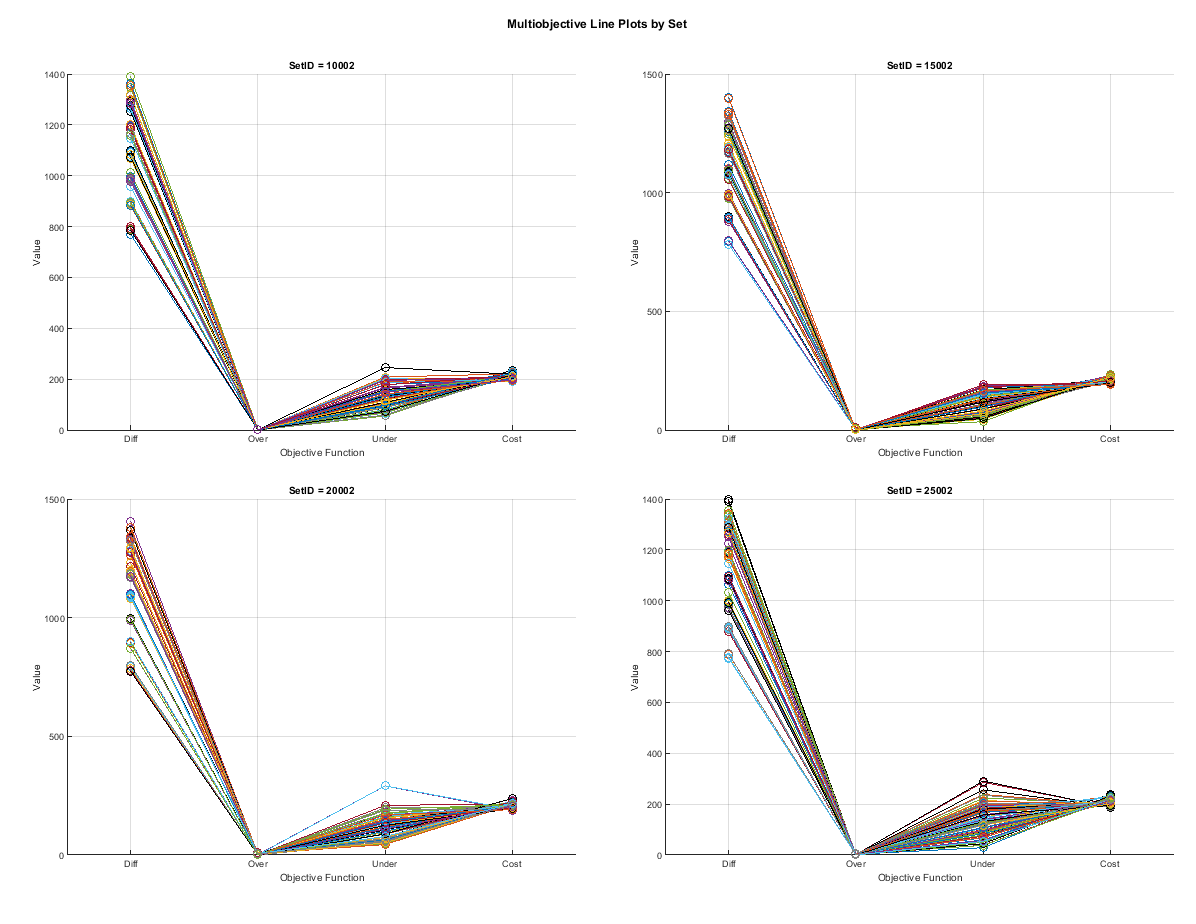

% Comparison multiobject from different set
for k=1:length(setids)
    if mod(k-1,4)==0, [~,a] = create2x2Axes('Multiobjective Line Plots by Set'); end
    subplot(a(mod(k-1,4)+1))
    hold on
    temp = Tsel(Tsel.SetID==setids(k),1:4);
    temp.Prodcost_avg = temp.Prodcost_avg*1e-3;
    for i=1:height(temp)
        plot(1:4,table2array(temp(i,:)),'marker','o','color',colorder0(mod(i-1,size(colorder0,1))+1,:));
    end
    hold off
    xlim([0.5 4.5])
    xticks(1:4); xticklabels({'Diff','Over','Under','Cost'});
    xlabel('Objective Function');
    ylabel('Value');
    grid on
    title(sprintf('SetID = %d',setids(k)));
end